# Prey-Predator population

Instructions are in the task pane to the left. Complete and submit each task one at a time.

Do not edit. This code solves for the predator and prey populations for 3 weeks, with 10 prey and 2 predators initially.

tRange = [0 3];
Y0 = [10; 2];
[tSol, YSol] = ode45(@odefun, tRange, Y0);

## Task 1

The first column of the solution matrix `YSol` represents *x*, the prey population.

x = YSol(:, 1);

## Task 2

The second column of the solution matrix `YSol` represents *y*, the predator population.

y = YSol(:, 2);

## Task 3

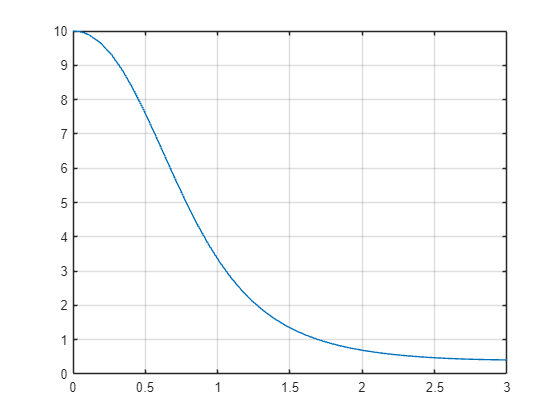

plot(tSol, x)
grid on

## Task 4

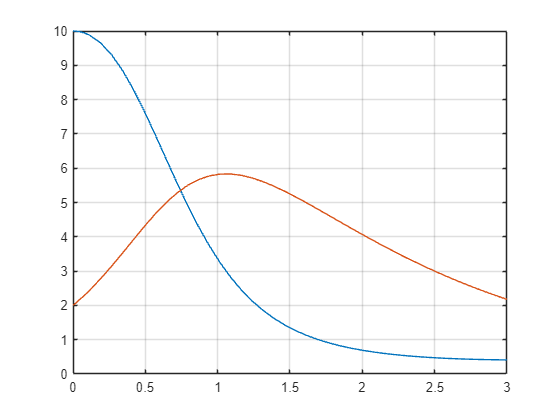

hold on
plot(tSol, y)
grid on
hold off

## Task 5

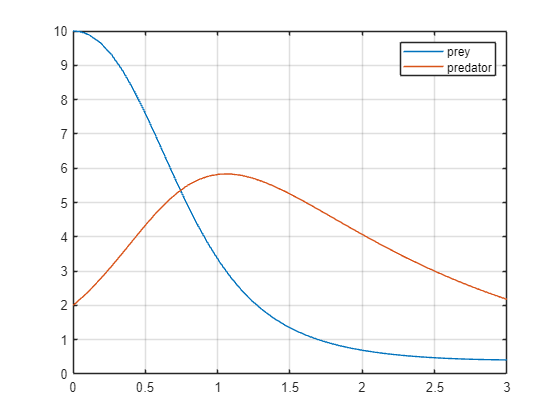

legend("prey", "predator")

## Task 6

ymax = max(y)

ymax = 5.8315

**ODE function**

Do not edit. This code defines the ODE function for the system of ODEs

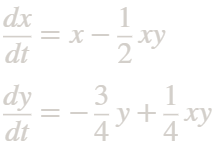

function dYdt = odefun(t, Y)
    x = Y(1); % prey
    y = Y(2); % predator
    dxdt = x - 1/2*x*y;
    dydt = -3/4*y + 1/4*x*y;
    dYdt = [dxdt; dydt];
end